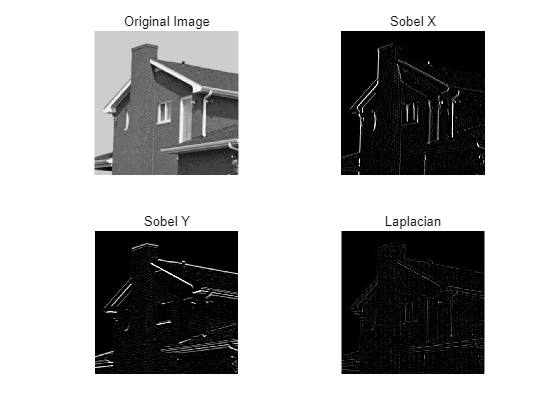

% Load the image
img = imread('images/house.tif');


% Define the Sobel and Laplacian filters
sobel_x = [-1 0 1; -2 0 2; -1 0 1];
sobel_y = [-1 -2 -1; 0 0 0; 1 2 1];
laplacian = [0 -1 0; -1 4 -1; 0 -1 0];

% Apply the Sobel filters in both the x and y directions
sobel_x_img = my_conv(double(img), sobel_x);
sobel_y_img = my_conv(double(img), sobel_y);

% Apply the Laplacian filter
laplacian_img = my_conv(double(img), laplacian);

% Display the original image and the filtered images
subplot(2, 2, 1); imshow(img); title('Original Image');
subplot(2, 2, 2); imshow(sobel_x_img, []); title('Sobel X');
subplot(2, 2, 3); imshow(sobel_y_img, []); title('Sobel Y');
subplot(2, 2, 4); imshow(laplacian_img, []); title('Laplacian');

function [result] = my_conv(M, K)
result = zeros(size(M));
M_pad = padarray(M, size(K)-1, 'replicate');
M_pad = double(M_pad);
for i = 1:size(M,1)
    for j =1:size(M,2)
        M_crop = M_pad(i:i+size(K,1)-1,j:j+size(K,2)-1);
        for m = 1:size(K, 1)
            for n = 1:size(K, 2)
                result(i,j)=result(i,j)+M_crop(m,n)*K(size(K,1)-m+1, size(K,2)-n+1);
            end
        end
    end
end
result = uint8(result);
end